% Touch-stone file to png

% Documents:
%  RF Network Parameter Objects : https://jp.mathworks.com/help/rf/ug/rf-network-parameter-objects.html?searchHighlight=z%20parameter&s_tid=srchtitle_z%20parameter_6
%  Interpolate network parameter data at new frequencies : https://jp.mathworks.com/help/rf/ref/rfinterp1.html
%  SmithPlot Properties : https://jp.mathworks.com/help/rf/ref/smithplot-properties.html?searchHighlight=smithplot&s_tid=srchtitle_smithplot_4
% ------------------------------------------------------
clear;
close all;
clc;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

buff_title = 'TEST PLOTS';
file0 = '20230107_L10_LowHeight_Dipole_v6.5ASYN.s1p';

xlim_min = 1; 
xlim_max = 10;

usrLineColorOrder = [0 0 0; 1 0 0; 0 0 1];

flag_ieee_format = 1;

% ------------------------------------------------------

sp0_org = sparameters(file0);
sp0_freq_org = sp0_org.Frequencies;

sp0_freq = sp0_freq_org(1):1e6:sp0_freq_org(end);   % New frequency plan for the interpolation with 1 MHz
sp0 = rfinterp1(sp0_org, sp0_freq);                 % Interpolation process

zp0_org = zparameters(file0);       % https://jp.mathworks.com/help/rf/ref/zparameters.html
zp0 = rfinterp1(zp0_org, sp0_freq);

% CALC: ================================================
%  RF ToolBox: https://jp.mathworks.com/help/rf/frequency-domain-analysis.html

% 1) VSWR
% 2) LOGMAG
% 3) Smith chart
% 4) Z-parameter [Real/Imaginary]
% 5) Phase

sp0_s11_vswr    = (1+abs(rfparam(sp0,1,1)))./(1-abs(rfparam(sp0,1,1)));    % VSWR
vswr2_line      = 2 + 0*abs(rfparam(sp0,1,1));                             % VSWR 2 line
vswr3_line      = 3 + 0*abs(rfparam(sp0,1,1));                             % VSWR 3 line

sp0_s11_LOGMAG  = 20*log10(abs(rfparam(sp0,1,1)));
s11_n10dB_line  = -10 + 0*abs(rfparam(sp0,1,1));

sp0_s11_phase       = 180/pi*angle(rfparam(sp0,1,1));
sp0_s11_phase_unwrap= 180/pi*unwrap(angle(rfparam(sp0,1,1)));

%sp0_z11_complex = s2z(rfparam(sp0,1,1),50);
sp0_z11_abs     = abs(rfparam(zp0,1,1));
sp0_z11_real    = real(rfparam(zp0,1,1));
sp0_z11_imag    = imag(rfparam(zp0,1,1));

% smith plot
[sp0_smith_freq, sp0_smith_rfparam] = rfparam_rangecut(4e9,8e9,sp0_freq,rfparam(sp0,1,1));
sp0_smith_freq_start    = sp0_smith_freq(1);
sp0_smith_freq_stop     = sp0_smith_freq(end);
sp0_smith_rfparam_start = sp0_smith_rfparam(1);
sp0_smith_rfparam_stop  = sp0_smith_rfparam(end);

% PLOT: ================================================

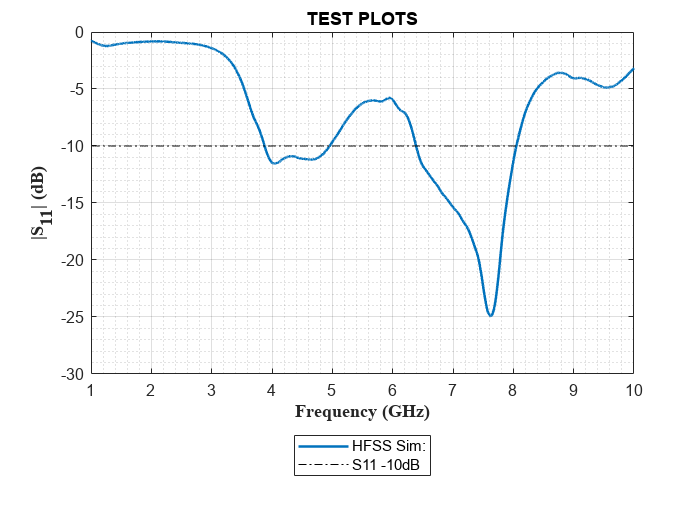


figure;
hold on;
plot(sp0_freq/1e9,sp0_s11_LOGMAG,'DisplayName','HFSS Sim: ','LineWidth',1.5);
plot(sp0_freq/1e9,s11_n10dB_line,'DisplayName','S11 -10dB','Color',[0 0 0],'LineStyle','-.');

title(buff_title);
xlabel('Frequency (GHz)','FontWeight','bold','FontName','Times New Roman')
ylabel('|S_{11}| (dB)'  ,'FontWeight','bold','FontName','Times New Roman')
legend('Location','southoutside');

xlim([xlim_min xlim_max]);
ylim([-30 0]);

if(flag_ieee_format==1)
    ax = gca;   % set the aexes property to ax.
    set(ax,'FontName','Times New Roman','XMinorGrid','off','YMinorGrid','off','ZMinorGrid','off','FontSize',19,'FontWeight','bold','LineWidth',1,'ZGrid','on', 'XTick', xlim_min:1:xlim_max);
    ax.ColorOrder = usrLineColorOrder;
    ax.LineStyleOrder = {'-','-'};
    box on;
    axis on;
    grid off;
else
    box on;
    axis on;
    grid on;
    grid minor;
end

hold off;

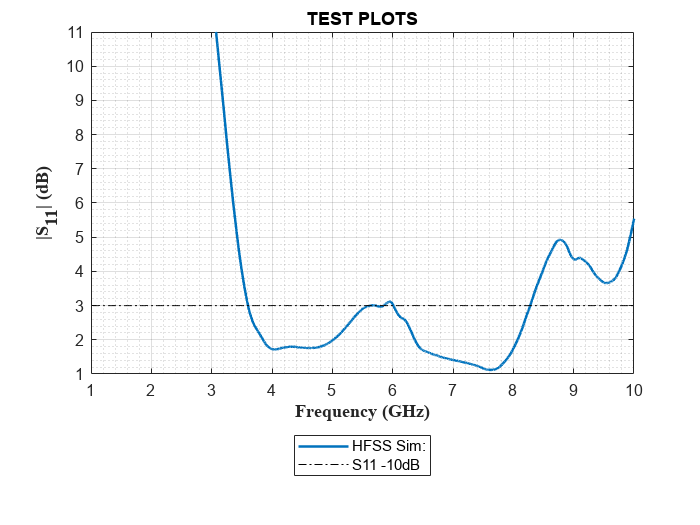


figure;
hold on;
plot(sp0_freq/1e9,sp0_s11_vswr,'DisplayName','HFSS Sim: ','LineWidth',1.5);
plot(sp0_freq/1e9,vswr3_line,'DisplayName','S11 -10dB','Color',[0 0 0],'LineStyle','-.');

title(buff_title);
xlabel('Frequency (GHz)','FontWeight','bold','FontName','Times New Roman')
ylabel('|S_{11}| (dB)','FontWeight','bold','FontName','Times New Roman')
legend('Location','southoutside');

xlim([xlim_min xlim_max]);
ylim([1 11]);

if(flag_ieee_format==1)
    ax = gca;   % set the aexes property to ax.
    set(ax,'FontName','Times New Roman','XMinorGrid','off','YMinorGrid','off','ZMinorGrid','off','FontSize',19,'FontWeight','bold','LineWidth',1,'ZGrid','on', 'XTick', xlim_min:1:xlim_max);
    ax.ColorOrder = usrLineColorOrder;
    ax.LineStyleOrder = {'-','-'};
    box on;
    axis on;
    grid off;
else
    box on;
    axis on;
    grid on;
    grid minor;
end


hold off;

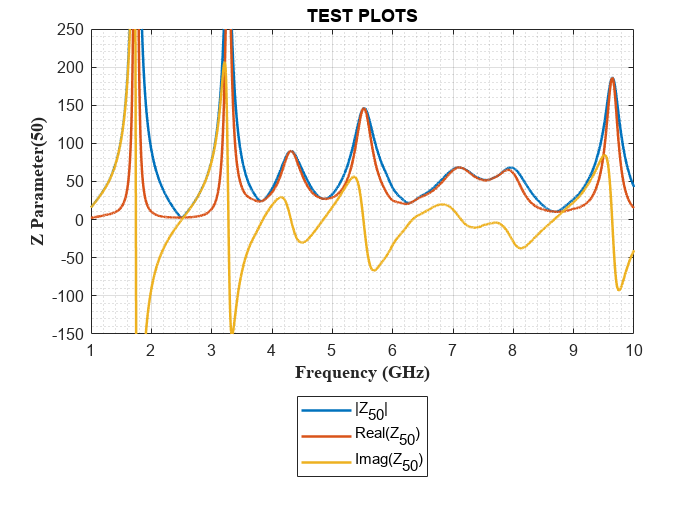




figure;
hold on;
plot(sp0_freq/1e9, sp0_z11_abs, 'DisplayName', '|Z_{50}|', 'LineWidth', 1.5);
plot(sp0_freq/1e9, sp0_z11_real, 'DisplayName', 'Real(Z_{50})', 'LineWidth', 1.5);
plot(sp0_freq/1e9, sp0_z11_imag, 'DisplayName', 'Imag(Z_{50})', 'LineWidth', 1.5);

title(buff_title);
xlabel('Frequency (GHz)','FontWeight','bold','FontName','Times New Roman')
ylabel('Z Parameter(50)','FontWeight','bold','FontName','Times New Roman')
legend('Location','southoutside');

xlim([xlim_min xlim_max]);
ylim([-150 250]);

if(flag_ieee_format==1)
    ax = gca;   % set the aexes property to ax.
    set(ax,'FontName','Times New Roman','XMinorGrid','off','YMinorGrid','off','ZMinorGrid','off','FontSize',19,'FontWeight','bold','LineWidth',1,'ZGrid','on', 'XTick', xlim_min:1:xlim_max);
    ax.ColorOrder = usrLineColorOrder;
    ax.LineStyleOrder = {'-','-'};
    box on;
    axis on;
    grid off;
else
    box on;
    axis on;
    grid on;
    grid minor;
end

hold off;

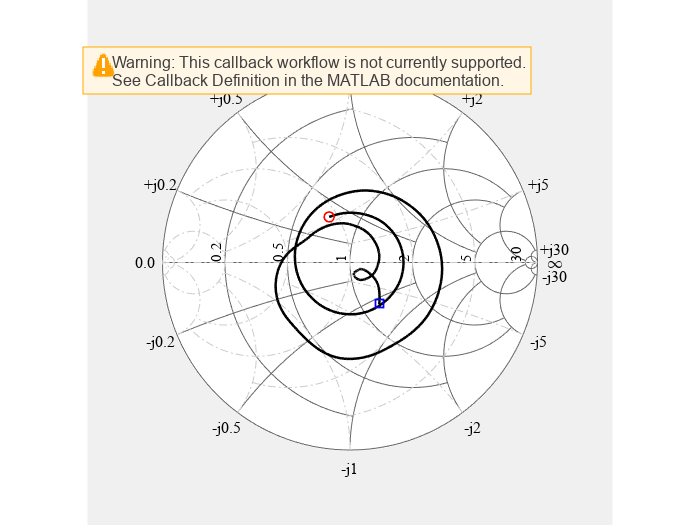

figure;
% Document: https://jp.mathworks.com/help/rf/ref/smithplot-properties.html?searchHighlight=smithplot&s_tid=srchtitle_smithplot_4
%h = smithplot(sp0.Frequencies, rfparam(sp0,1,1),'GridType','ZY');

h = smithplot(sp0_smith_freq, sp0_smith_rfparam,'GridType','ZY');
hold on;
smithplot(sp0_smith_freq_start, sp0_smith_rfparam_start);
smithplot(sp0_smith_freq_stop, sp0_smith_rfparam_stop);
h.LineWidth     = [1.5;1;1];
h.LineStyle     = {'-','-','-'};
h.ColorOrder    = usrLineColorOrder;
%h.LegendLabels  = {'S_11'};
h.Marker        = {'none', 'o', 'square'};
h.FontName = 'Times New Roman';
h.GridLineWidth = 0.5;
%h.GridSubLineWidth = 0.8;
hold off;

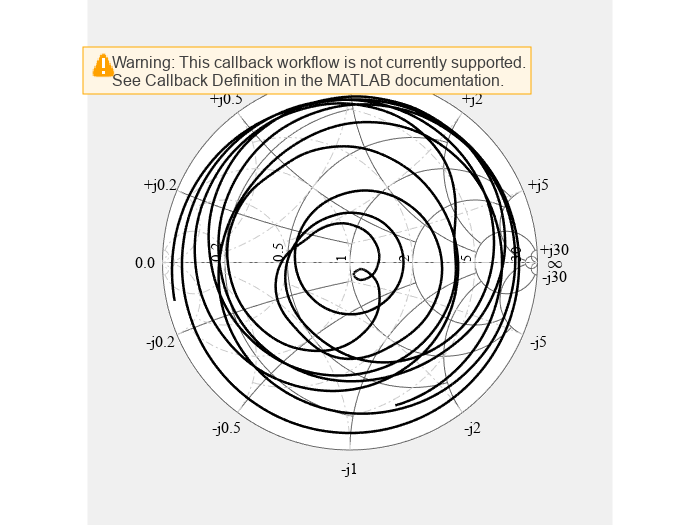

figure;
% Document: https://jp.mathworks.com/help/rf/ref/smithplot-properties.html?searchHighlight=smithplot&s_tid=srchtitle_smithplot_4
h = smithplot(sp0.Frequencies, rfparam(sp0,1,1),'GridType','ZY');
hold on;
h.LineWidth     = [1.5;1;1];
h.LineStyle     = {'-','-','-'};
h.ColorOrder    = usrLineColorOrder;
%h.LegendLabels  = {'S_11'};
h.Marker        = {'none', 'o', 'square'};
h.FontName = 'Times New Roman';
h.GridLineWidth = 0.5;
%h.GridSubLineWidth = 0.8;
hold off;

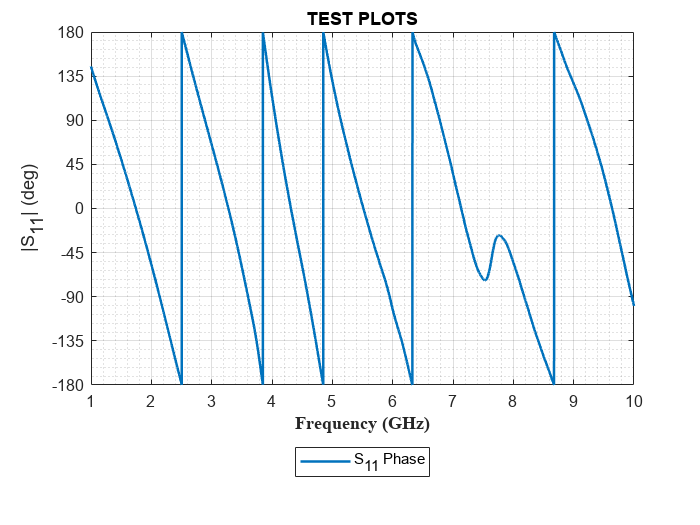

figure;
plot(sp0_freq/1e9,sp0_s11_phase, 'DisplayName', 'S_{11} Phase', 'LineWidth', 1.5);

title(buff_title);
xlabel('Frequency (GHz)','FontWeight','bold','FontName','Times New Roman');
ylabel('|S_{11}| (deg)');
legend('Location','southoutside');


xlim([xlim_min xlim_max]);
ylim([-180 180])
yticks([-180 -135 -90 -45 0 45 90 135 180]);

if(flag_ieee_format==1)
    ax = gca;   % set the aexes property to ax.
    set(ax,'FontName','Times New Roman','XMinorGrid','off','YMinorGrid','off','ZMinorGrid','off','FontSize',19,'FontWeight','bold','LineWidth',1,'ZGrid','on', 'XTick', xlim_min:1:xlim_max);
    ax.ColorOrder = usrLineColorOrder;
    ax.LineStyleOrder = {'-','-'};
    box on;
    axis on;
    grid off;
else
    box on;
    axis on;
    grid on;
    grid minor;
end

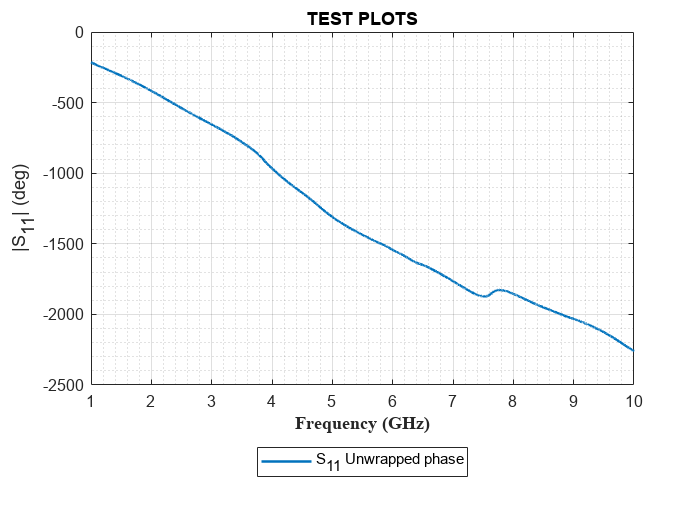



figure;
plot(sp0_freq/1e9,sp0_s11_phase_unwrap, 'DisplayName', 'S_{11} Unwrapped phase', 'LineWidth', 1.5);

title(buff_title);
xlabel('Frequency (GHz)','FontWeight','bold','FontName','Times New Roman')
ylabel('Z Parameter(50)','FontWeight','bold','FontName','Times New Roman')
ylabel('|S_{11}| (deg)')
legend('Location','southoutside');


xlim([xlim_min xlim_max]);

if(flag_ieee_format==1)
    ax = gca;   % set the aexes property to ax.
    set(ax,'FontName','Times New Roman','XMinorGrid','off','YMinorGrid','off','ZMinorGrid','off','FontSize',19,'FontWeight','bold','LineWidth',1,'ZGrid','on', 'XTick', xlim_min:1:xlim_max);
    ax.ColorOrder = usrLineColorOrder;
    ax.LineStyleOrder = {'-','-'};
    box on;
    axis on;
    grid off;
else
    box on;
    axis on;
    grid on;
    grid minor;
end